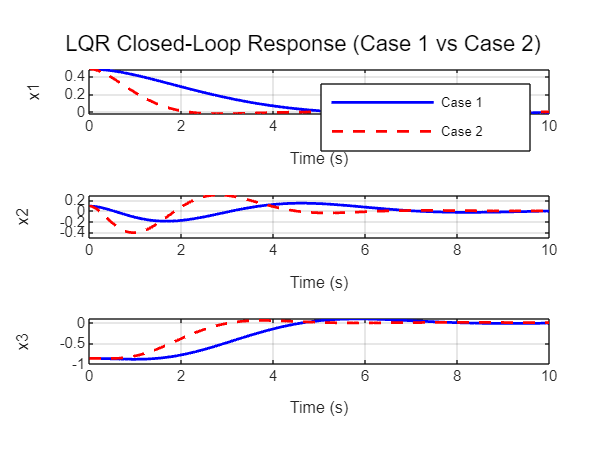

%% ================ Exercise 2: 3DOF Helicopter (Complete) =================
clear; clc; close all;

%% System Matrices (given)
A = [ 0     0     0     1     0     0;
      0     0     0     0     1     0;
      0     0     0     0     0     1;
      0     0     0     0     0     0;
      0     0     0     0     0     0;
      0  -1.2304  0     0     0     0];

B = [ 0      0;
      0      0;
      0      0;
      0.0858 0.0858;
      0.5810 -0.5810;
      0      0];

% Initial condition
X0 = [0.479; 0.0872; -0.8726; 0; 0; 0];

% Simulation time
tspan = [0 10];

%% ========== Part 1: LQR Controllers (Case 1 and Case 2) + Simulation ==========
% We have two sets of R:
%   Case 1: R = diag([10 10])
%   Case 2: R = diag([0.25 0.25])
% The same Q is used for both:
Q_lqr = diag([100, 1, 10, 0, 0, 2]);

R_case1 = diag([10, 10]);
R_case2 = diag([0.25, 0.25]);

K1 = lqr(A, B, Q_lqr, R_case1);
K2 = lqr(A, B, Q_lqr, R_case2);

A_cl1 = A - B*K1;
A_cl2 = A - B*K2;

% Simulate both closed loops
[t1, X_case1] = ode45(@(t,x) A_cl1*x, tspan, X0);
[t2, X_case2] = ode45(@(t,x) A_cl2*x, tspan, X0);

% Plot states x1, x2, x3 for comparison
figure;
subplot(3,1,1);
plot(t1, X_case1(:,1), 'b-', t2, X_case2(:,1), 'r--', 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('x1'); legend('Case 1','Case 2'); grid on;

subplot(3,1,2);
plot(t1, X_case1(:,2), 'b-', t2, X_case2(:,2), 'r--', 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('x2'); grid on;

subplot(3,1,3);
plot(t1, X_case1(:,3), 'b-', t2, X_case2(:,3), 'r--', 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('x3'); grid on;
sgtitle('LQR Closed-Loop Response (Case 1 vs Case 2)');


%% ========== Part 2: Recovery Region for a Given Controller (Case 1) ==========
% We define the "recovery region" ellipsoid x'Qx <= 1 subject to:
%   A_cl1'*Q + Q*A_cl1 <= -eps*I, Q>0,
%   alpha_i'*Q*alpha_i <= 1 for all i.
% Normalized constraints for states and inputs (u=-K1*x).

epsilon = 1e-6;  % Tolerance

% Build alpha vectors for constraints:
%  (1) |x1| <= 0.5233  => alpha=[1/0.5233,0,0,0,0,0], etc.
a_s1 = [1/0.5233; 0; 0; 0; 0; 0]; a_s2 = -a_s1;
%  (2) |x2| <= 0.174
a_s3 = [0; 1/0.174; 0; 0; 0; 0];  a_s4 = -a_s3;
%  (3) |x3| <= 3.14
a_s5 = [0; 0; 1/3.14; 0; 0; 0];   a_s6 = -a_s5;
%  (4) |x5| <= 0.174
a_s7 = [0; 0; 0; 0; 1/0.174; 0];  a_s8 = -a_s7;
% Input constraints: |u1|<=24, |u2|<=24 with u=-K1*x => K1(1,:)*x <= 24
a_in1 = (K1(1,:)'/24); a_in2 = -a_in1;
a_in3 = (K1(2,:)'/24); a_in4 = -a_in3;

alpha_case1 = [a_s1,a_s2,a_s3,a_s4,a_s5,a_s6,a_s7,a_s8, a_in1,a_in2,a_in3,a_in4];

% Solve the LMI
Q_rec1 = sdpvar(6,6,'symmetric');
Constraints1 = [Q_rec1 >= epsilon*eye(6), A_cl1'*Q_rec1 + Q_rec1*A_cl1 <= -epsilon*eye(6)];
for i=1:size(alpha_case1,2)
    Constraints1 = [Constraints1, alpha_case1(:,i)'*Q_rec1*alpha_case1(:,i) <= 1];
end
Obj1 = -logdet(Q_rec1);

options = sdpsettings('solver','sdpt3','verbose',1);
sol1 = optimize(Constraints1, Obj1, options);


 num. of constraints = 21
 dim. of sdp    var  = 18,   num. of sdp  blk  =  3
 dim. of linear var  = 12
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+02|3.7e+01|7.5e+03| 1.061844e+02  1.981551e+01| 0:0:00| chol  1  1 
 1|0.652|0.419|3.1e+02|2.2e+01|4.8e+03| 9.692680e+01  1.886741e+01| 0:0:00| chol  1  1 
 2|0.953|0.574|5.0e+01|9.3e+00|2.4e+03| 1.037501e+02  1.527199e+01| 0:0:00| chol  1  1 
 3|1.000|0.759|6.9e+01|2.2e+00|6.5e+02| 9.783815e+01  8.641863e+00| 0:0:00| chol  1  1 
 4|1.000|0.906|4.9e+01|2.1e-01|9.6e+01| 5.674921e+01 -2.356054e+00| 0:0:00| chol  1  1 
 5|0.987|0.912|4.4e+01|1.9e-02|8.8e+00|-7.44

if sol1.problem == 0
    Q_rec_opt1 = value(Q_rec1);
    disp('Q_rec for Case 1:'); disp(Q_rec_opt1);
else
    error('Recovery region (Case 1) failed: %s', sol1.info);
end

Q_rec for Case 1:
    0.2738   -0.0000    0.0000    0.3126   -0.0000    0.0000
   -0.0000    0.0303   -0.0105   -0.0000    0.0094   -0.0201
    0.0000   -0.0105    0.0182    0.0000   -0.0014    0.0053
    0.3126   -0.0000    0.0000    2.4366   -0.0000    0.0000
   -0.0000    0.0094   -0.0014   -0.0000    0.0303   -0.0431
    0.0000   -0.0201    0.0053    0.0000   -0.0431    0.0877





%% ========== Part 3: Recovery Region for a Given Controller (Case 2) ==========
% Same approach, but for K2.

A_cl2 = A - B*K2;
Q_rec2 = sdpvar(6,6,'symmetric');

% Constraint vectors for K2 input:
a_in1_2 = (K2(1,:)'/24); a_in2_2 = -a_in1_2;
a_in3_2 = (K2(2,:)'/24); a_in4_2 = -a_in3_2;

alpha_case2 = [a_s1,a_s2,a_s3,a_s4,a_s5,a_s6,a_s7,a_s8, a_in1_2,a_in2_2,a_in3_2,a_in4_2];

Constraints2 = [Q_rec2 >= epsilon*eye(6), A_cl2'*Q_rec2 + Q_rec2*A_cl2 <= -epsilon*eye(6)];
for i=1:size(alpha_case2,2)
    Constraints2 = [Constraints2, alpha_case2(:,i)'*Q_rec2*alpha_case2(:,i) <= 1];
end
Obj2 = -logdet(Q_rec2);

sol2 = optimize(Constraints2, Obj2, options);


 num. of constraints = 21
 dim. of sdp    var  = 18,   num. of sdp  blk  =  3
 dim. of linear var  = 12
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.0e+02|4.0e+01|8.4e+03| 1.061844e+02  1.981551e+01| 0:0:00| chol  1  1 
 1|0.681|0.678|2.9e+02|1.3e+01|3.2e+03| 9.611209e+01  1.609391e+01| 0:0:00| chol  1  1 
 2|1.000|0.608|6.3e+01|5.0e+00|1.7e+03| 1.294405e+02  1.138925e+01| 0:0:00| chol  1  1 
 3|0.333|0.725|1.7e+02|1.4e+00|4.9e+02| 1.224149e+02  6.929509e+00| 0:0:00| chol  1  1 
 4|1.000|0.781|4.7e+01|3.0e-01|1.3e+02| 6.402037e+01 -1.508816e+00| 0:0:00| chol  1  1 
 5|0.843|0.379|1.0e+02|1.9e-01|8.3e+01| 2.96

if sol2.problem == 0
    Q_rec_opt2 = value(Q_rec2);
    disp('Q_rec for Case 2:'); disp(Q_rec_opt2);
else
    error('Recovery region (Case 2) failed: %s', sol2.info);
end

Q_rec for Case 2:
    0.2738    0.0000    0.0000    0.1243    0.0000    0.0000
    0.0000    0.0303   -0.0264    0.0000    0.0086   -0.0388
    0.0000   -0.0264    0.1105   -0.0000   -0.0046    0.0257
    0.1243    0.0000   -0.0000    0.3853    0.0000   -0.0000
    0.0000    0.0086   -0.0046    0.0000    0.0157   -0.0538
    0.0000   -0.0388    0.0257   -0.0000   -0.0538    0.2511



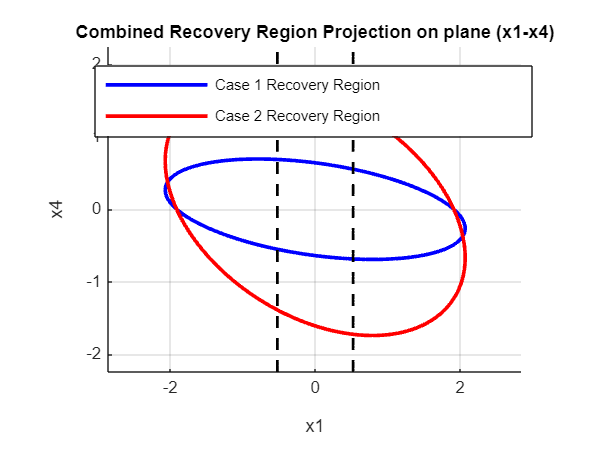

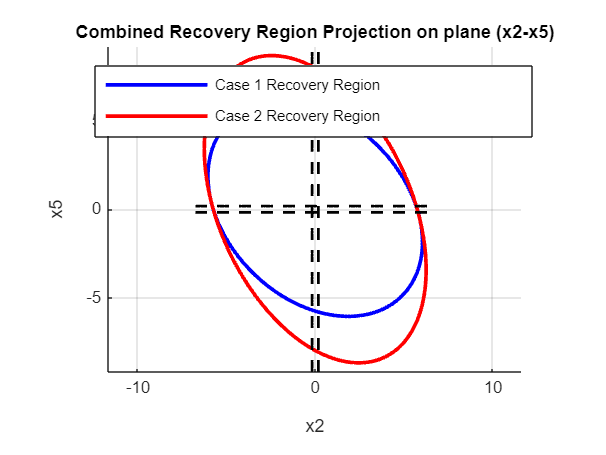

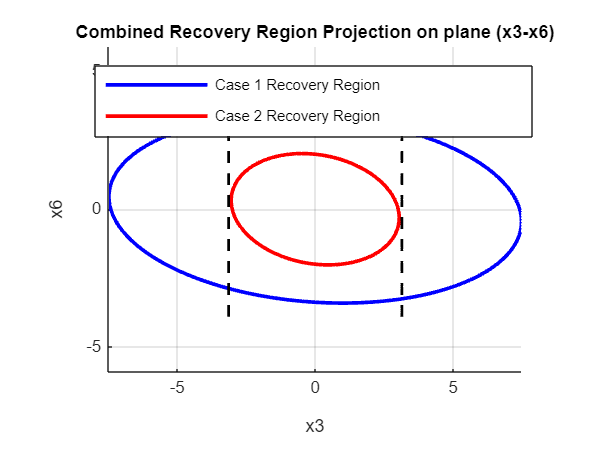


%% ========== Combined Recovery Region Projections for Case 1 and Case 2 ==========
% Define the projection planes:
%   Plane 1: indices [1,4] (x1-x4)
%   Plane 2: indices [2,5] (x2-x5)
%   Plane 3: indices [3,6] (x3-x6)
planes = { [1,4], [2,5], [3,6] };
planeNames = {'(x1-x4)', '(x2-x5)', '(x3-x6)'};

% Define constraint boundaries for the projection planes:
% Each element: [xmin, xmax, ymin, ymax]
% If no constraint for a coordinate, use NaN.
% For x1-x4: x1 constrained by ±0.5233; x4 unconstrained.
boundaries = { [ -0.5233, 0.5233, NaN, NaN ], ...  
               [ -0.174,  0.174,  -0.174, 0.174 ], ...  
               [ -3.14,   3.14,   NaN,   NaN ] };

% Loop over the three planes:
for p = 1:length(planes)
    idx = planes{p};
    
    % Extract the 2x2 submatrices from the recovery region matrices for each case.
    Q_sub_case1 = Q_rec_opt1(idx, idx);
    Q_sub_case2 = Q_rec_opt2(idx, idx);
    
    % Generate a unit circle.
    theta = linspace(0, 2*pi, 200);
    unitCircle = [cos(theta); sin(theta)];
    
    % Compute the ellipsoidal boundaries:
    ellip_case1 = sqrtm(inv(Q_sub_case1)) * unitCircle;
    ellip_case2 = sqrtm(inv(Q_sub_case2)) * unitCircle;
    
    % Create a figure.
    figure; hold on; grid on; axis equal;
    
    % Plot recovery region ellipses.
    h1 = plot(ellip_case1(1,:), ellip_case1(2,:), 'b-', 'LineWidth',2);
    h2 = plot(ellip_case2(1,:), ellip_case2(2,:), 'r-', 'LineWidth',2);
    
    % Plot constraint boundaries if defined.
    bounds = boundaries{p};
    % Vertical boundaries (for x-coordinate):
    if ~isnan(bounds(1)) && ~isnan(bounds(2))
        % Determine a suitable y-range from the ellipsoid plot.
        y_min = min([ellip_case1(2,:) ellip_case2(2,:)]) - 0.5;
        y_max = max([ellip_case1(2,:) ellip_case2(2,:)]) + 0.5;
        plot(bounds(1)*ones(1,100), linspace(y_min, y_max, 100), 'k--', 'LineWidth',1.5);
        plot(bounds(2)*ones(1,100), linspace(y_min, y_max, 100), 'k--', 'LineWidth',1.5);
    end
    % Horizontal boundaries (for y-coordinate):
    if ~isnan(bounds(3)) && ~isnan(bounds(4))
        % Determine a suitable x-range from the ellipsoid plot.
        x_min = min([ellip_case1(1,:) ellip_case2(1,:)]) - 0.5;
        x_max = max([ellip_case1(1,:) ellip_case2(1,:)]) + 0.5;
        plot(linspace(x_min, x_max, 100), bounds(3)*ones(1,100), 'k--', 'LineWidth',1.5);
        plot(linspace(x_min, x_max, 100), bounds(4)*ones(1,100), 'k--', 'LineWidth',1.5);
    end
    
    % Label axes: use x(i) for the first and x(j) for the second coordinate.
    xlabel(['x' num2str(idx(1))]);
    ylabel(['x' num2str(idx(2))]);
    title(['Combined Recovery Region Projection on plane ' planeNames{p}]);
    
    % Create legend.
    legend([h1, h2], {'Case 1 Recovery Region', 'Case 2 Recovery Region'}, 'Location','best');
    
    hold off;
end



%% ========== Part 4: Maximal Recovery Region Synthesis (Controller Synthesis) ==========
% Now we let the controller be free (K is unknown). We use Y=KQ approach:
%   A*Q + Q*A' - B*Y - Y'*B' < 0,  Q>0
%   alpha_i'*Q*alpha_i <= 1
%   minimize -logdet(Q)

% Scaling parameters based on state constraints:
x1_scale = 0.5233;  % |x1| ≤ 0.5233 rad
x2_scale = 0.174;   % |x2| ≤ 0.174 rad
x3_scale = 3.14;    % |x3| ≤ 3.14 rad
x5_scale = 0.174;   % |x5| ≤ 0.174 rad/s
% For states without explicit constraints, assume a scale of 1:
x4_scale = 1.0;     % x4 (elevation rate)
x6_scale = 1.0;     % x6 (travel rate)

scale_factors = [x1_scale; x2_scale; x3_scale; x4_scale; x5_scale; x6_scale];
inv_scale = diag(1./scale_factors);
epsilon = 1e-4;  % Increased tolerance for better numerical stability

% Scaled system matrices:
A_scaled = inv_scale * A * diag(scale_factors);
B_scaled = inv_scale * B;

% Decision variables for the robust synthesis:
Q_max = sdpvar(6,6, 'symmetric');
Y = sdpvar(2,6, 'full');  % Note: Y = K*Q in the change-of-variables formulation

% Build constraints:
Constraints_max = [];

% 1. Q_max must be positive definite:
Constraints_max = [Constraints_max, Q_max >= epsilon*eye(6)];

% 2. Scaled Lyapunov inequality:
LMI_max = A_scaled*Q_max + Q_max*A_scaled' - B_scaled*Y - Y'*B_scaled';
Constraints_max = [Constraints_max, LMI_max <= -epsilon*eye(6)];

% 3. State constraints (scaled):
% For |x1| ≤ 0.5233, |x2| ≤ 0.174, |x3| ≤ 3.14.
% (We do not include x5 here, but you can add similar lines if needed.)
alpha = [...
    [1/0.5233; 0; 0; 0; 0; 0], ...  % x1 constraint: x1/0.5233 ≤ 1
    [0; 1/0.174; 0; 0; 0; 0], ...    % x2 constraint: x2/0.174 ≤ 1
    [0; 0; 1/3.14; 0; 0; 0]          % x3 constraint: x3/3.14 ≤ 1
    ];

% Add each constraint: alpha_i' * Q_max * alpha_i <= 1
for i = 1:size(alpha,2)
    Constraints_max = [Constraints_max, alpha(:,i)' * Q_max * alpha(:,i) <= 1];
end

% 4. Objective: maximize the volume of the ellipsoid {x: x' Q_max x <= 1}
% Equivalently, minimize -log(det(Q_max)) with a small regularization.
Objective_max = -logdet(Q_max) + 1e-4*norm(Q_max,'fro') + 1e-4*norm(Y,'fro');

% Solver options - try multiple solvers:
solvers_to_try = {'mosek', 'sdpt3', 'sedumi'};
solver_success = false;

for solver = solvers_to_try
    try
        options = sdpsettings('solver', solver{1}, 'verbose', 2, 'debug', 1);
        sol_max = optimize(Constraints_max, Objective_max, options);
        
        if sol_max.problem == 0
            solver_success = true;
            break;
        end
    catch
        fprintf('Solver %s failed, trying next solver...\n', solver{1});
    end
end


 num. of constraints = 35
 dim. of sdp    var  = 18,   num. of sdp  blk  =  3
 dim. of socp   var  = 50,   num. of socp blk  =  2
 dim. of linear var  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.3e+02|2.6e+01|2.8e+03| 1.617249e+01  1.981551e+01| 0:0:00| chol  1  1 
 1|0.338|0.720|2.2e+02|7.3e+00|1.3e+03| 1.422929e+01  1.665644e+01| 0:0:00| chol  1  1 
 2|0.570|0.635|1.0e+02|2.7e+00|5.6e+02| 1.522957e+01  1.243715e+01| 0:0:00| chol  1  1 
 3|0.384|0.635|1.2e+02|9.8e-01|2.6e+02| 2.061075e+01  1.187636e+01| 0:0:00| chol  1  1 
 4|0.776|0.747|3.3e+01|2.5e-01|6.8e+01| 2.073304e+01  7.302170e+00| 0:0:00| chol


if solver_success
    Q_max_opt = value(Q_max);
    Y_opt = value(Y);
    
    % Rescale Q_max back to original coordinates:
    Q_max_opt = diag(scale_factors) * Q_max_opt * diag(scale_factors);
    Y_opt = Y_opt * diag(scale_factors);
    
    % Recover the controller gain: K_max = Y_opt / Q_max_opt
    K_max = Y_opt / Q_max_opt;
    
    disp('Optimal Q (maximal recovery):');
    disp(Q_max_opt);
    disp('Corresponding controller K_max:');
    disp(K_max);
    
    % Verify stability:
    A_cl_max = A - B*K_max;
    eig_cl = eig(A_cl_max);
    if any(real(eig_cl) >= 0)
        warning('Controller is not stabilizing! Most positive eigenvalue: %f', max(real(eig_cl)));
    end
else
    error('All solvers failed. Last solver message: %s', sol_max.info);
end

Optimal Q (maximal recovery):


    0.0750    0.0000   -0.0000   -0.5895    0.0000    0.0000
    0.0000    0.0009    0.0997   -0.0000   -0.0009    0.0061
   -0.0000    0.0997   97.2117    0.0000    0.0026   -1.9852
   -0.5895   -0.0000    0.0000  654.2778   -0.0000   -0.0000
    0.0000   -0.0009    0.0026   -0.0000  291.2231    0.0006
    0.0000    0.0061   -1.9852   -0.0000    0.0006    0.3664



Corresponding controller K_max:


   1.0e+05 *

    0.4976    4.1065   -0.0063    0.0005    0.0000   -0.1028
    0.4976   -4.1065    0.0063    0.0005   -0.0000    0.1028



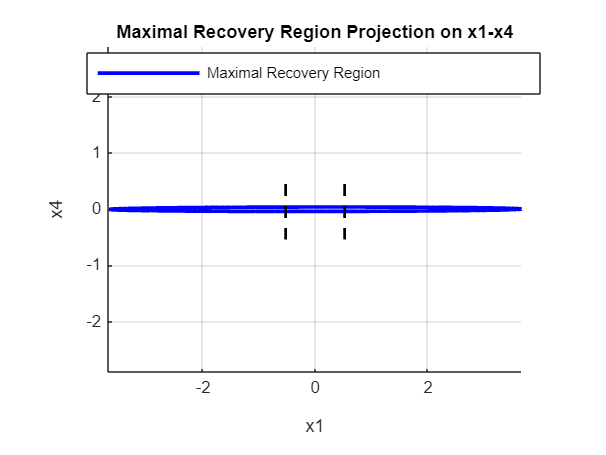

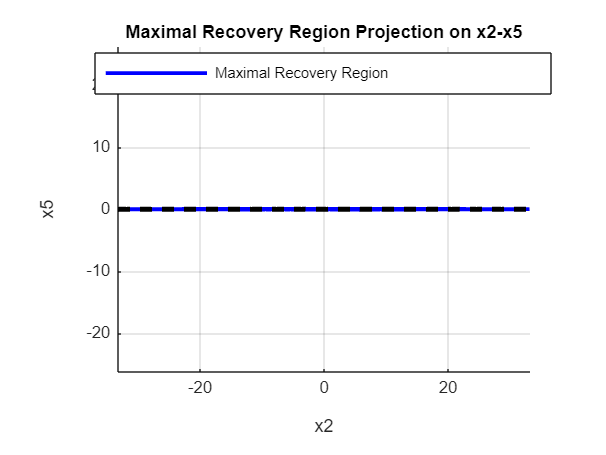

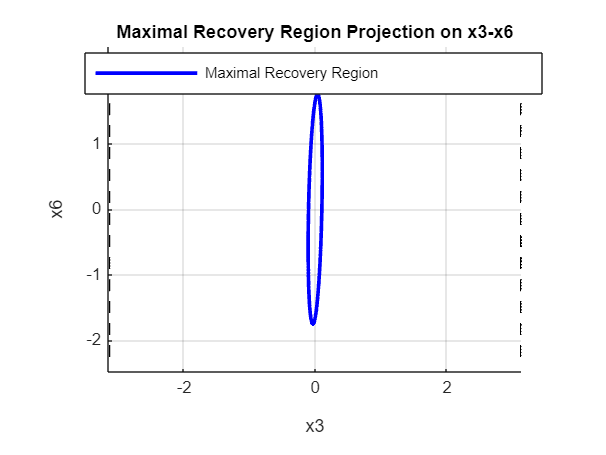


%% ==================== Plot Recovery Region Projections ====================
% We now plot the projections of the maximal recovery region (the ellipsoid {x: x''Q_max_opt x <= 1})
% on the following 2D planes:
%    Plane 1: x1-x4  (indices [1,4])
%    Plane 2: x2-x5  (indices [2,5])
%    Plane 3: x3-x6  (indices [3,6])
%
% For each plane we extract the corresponding 2x2 submatrix from Q_max_opt, compute the ellipse,
% and plot it with proper labels and legends.

planes = { [1,4], [2,5], [3,6] };
planeLabels = {'x1-x4','x2-x5','x3-x6'};

for p = 1:length(planes)
    idx = planes{p};
    Q_sub = Q_max_opt(idx, idx);
    
    % Generate a unit circle
    theta = linspace(0, 2*pi, 200);
    circle = [cos(theta); sin(theta)];
    
    % Compute ellipse points: { z: z' Q_sub z <= 1 } implies z = sqrtm(inv(Q_sub))*unitCircle
    ellipPts = sqrtm(inv(Q_sub)) * circle;
    
    % Create a new figure for this plane
    figure; hold on; grid on; axis equal;
    h = plot(ellipPts(1,:), ellipPts(2,:), 'b-', 'LineWidth', 2);
    
    % (Optional) Plot constraint boundaries if known.
    % For example, if the constraint for x1 is ±0.5233 on plane x1-x4, then:
    if isequal(idx, [1,4])
        x_bounds = [-0.5233, 0.5233];
        y_range = [min(ellipPts(2,:))-0.5, max(ellipPts(2,:))+0.5];
        plot(x_bounds(1)*ones(1,100), linspace(y_range(1), y_range(2),100), 'k--','LineWidth',1.5);
        plot(x_bounds(2)*ones(1,100), linspace(y_range(1), y_range(2),100), 'k--','LineWidth',1.5);
    elseif isequal(idx, [2,5])
        % x2 constraint ±0.174, and x5 constraint ±0.174
        x_bounds = [-0.174, 0.174];
        y_bounds = [-0.174, 0.174];
        x_range = [min(ellipPts(1,:))-0.2, max(ellipPts(1,:))+0.2];
        y_range = [y_bounds(1), y_bounds(2)];
        plot(x_bounds(1)*ones(1,100), linspace(y_range(1), y_range(2),100), 'k--','LineWidth',1.5);
        plot(x_bounds(2)*ones(1,100), linspace(y_range(1), y_range(2),100), 'k--','LineWidth',1.5);
        plot(linspace(x_range(1), x_range(2),100), y_bounds(1)*ones(1,100), 'k--','LineWidth',1.5);
        plot(linspace(x_range(1), x_range(2),100), y_bounds(2)*ones(1,100), 'k--','LineWidth',1.5);
    elseif isequal(idx, [3,6])
        % x3 constraint ±3.14 on plane x3-x6
        x_bounds = [-3.14, 3.14];
        x_range = [min(ellipPts(1,:))-0.5, max(ellipPts(1,:))+0.5];
        y_range = [min(ellipPts(2,:))-0.5, max(ellipPts(2,:))+0.5];
        plot(x_bounds(1)*ones(1,100), linspace(y_range(1), y_range(2),100), 'k--','LineWidth',1.5);
        plot(x_bounds(2)*ones(1,100), linspace(y_range(1), y_range(2),100), 'k--','LineWidth',1.5);
    end
    
    xlabel(['x' num2str(idx(1))]);
    ylabel(['x' num2str(idx(2))]);
    title(['Maximal Recovery Region Projection on ' planeLabels{p}]);
    legend(h, 'Maximal Recovery Region','Location','best');
    hold off;
end

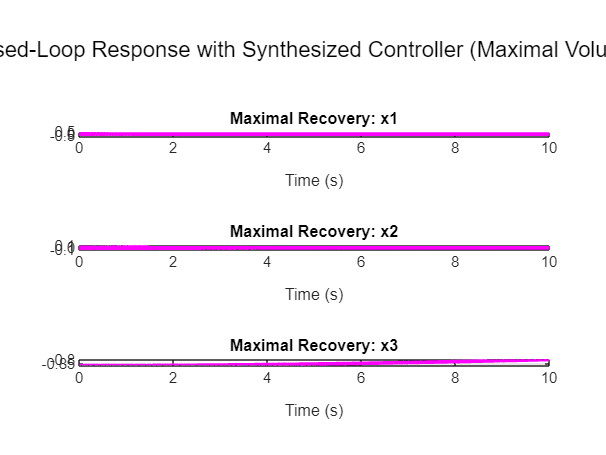


%% ========== Part 5: Simulation with the Maximal Recovery Controller ==========
A_cl_max = A - B*K_max;
[t_max, X_max] = ode45(@(t,x) A_cl_max*x, tspan, X0);

figure;
subplot(3,1,1); plot(t_max, X_max(:,1), 'm-', 'LineWidth',2); grid on;
xlabel('Time (s)'); ylabel('x1'); title('Maximal Recovery: x1');

subplot(3,1,2); plot(t_max, X_max(:,2), 'm-', 'LineWidth',2); grid on;
xlabel('Time (s)'); ylabel('x2'); title('Maximal Recovery: x2');

subplot(3,1,3); plot(t_max, X_max(:,3), 'm-', 'LineWidth',2); grid on;
xlabel('Time (s)'); ylabel('x3'); title('Maximal Recovery: x3');

sgtitle('Closed-Loop Response with Synthesized Controller (Maximal Volume)');


disp('Done! Check the figures for results.');

Done! Check the figures for results.
